url1 = 'http://homepages.cae.wisc.edu/~ece539/data/eeg/nic23a1.txt';
url2 = 'http://homepages.cae.wisc.edu/~ece539/data/eeg/nic23a3.txt'
nic23a1 = urlread(url1);
nic23a3 = urlread(url2);
% Use regular expressions to remove undesired markup.
%tx1 = regexprep(nic23a1,'<script.*?/script>','split');
tx1 = str2num(regexprep(nic23a1,'/t','split'));
tx2 = str2num(regexprep(nic23a3,'/t','split'));
[rows,cols] = size(tx1);
label1 = tx1(:,30:37);
label2 = tx2(:,30:37);

%(Bosonic)HF +1, 2 XX gates
L = 2;
%d = 0.75 %#(pA)
k = pi/100;
q = 2;
as = ones(L,L);
HR = 0
%HT = 0
G =[[0,1];[0,0]];
r = [0,0.35,1,0.15,1,0.4,0,0.1]; 
r = transpose(r);  %colum
%S1 = SGate1(L,r,2,k);
%S2 = SGate2(L,r,2,k);
S1 = SOperator();
S2 = SdgOperator();

H = Hamiltonian(2,2,2,2,2,k,L,S1,S2);
V = cov(r,r);
x = transpose(r(1:2:length(r)-1));
p = transpose(r(2:2:length(r)));
B = [x,p];
C = [ones(L,1), 1i*ones(L,1); ones(L,1), -1i*ones(L,1)];
AS = ones(L,L,L);
hr = ones(L,1);
a = ones(size(label1));
rou = a;
Qbest = ones(50,size(QCOV(r),1),L);


for n = 1:100
    for q = 1:L  %0-1
        as = as.*1/sqrt(L).*sum(exp(-1i*q*k).*H+randn(2));
        HR= HR + 0.5*sum(G.*as,[1,2]);
    end
    AS(q,:,:) = as;
    hr(q) = HR;
    %normalized
    routemp = updateRou(V, r, n, label1, a); 
    routemp1 = reshape(routemp(n,:),4,2); 
    Qsigma = QCOV(r);
    if mean(mean(abs(transpose(routemp1)*Qsigma)))>0.5
        Qtemp = Qsigma*routemp1;
        Qfun = Q(r, Qsigma); 
        Qfun1 = transpose(Qfun(1:2,:));
        Qfun2 = transpose(Qfun(3:4,:));        
        QFinal= Qtemp.*Qfun1+(ones(size(Qtemp))-Qtemp).*Qfun2;
    end
    if sum(QFinal) <= sum(Qbest(n,:,:))
        Qbest(n,:,:) = QFinal;
        if n>=50
            break
        end
    end
end

temp = reshape(Qbest,50,8);
meanQbest = temp;
stdQbest = temp;
%temp1 = unique(mean(Qbest,1));
figure(),
polar(temp);

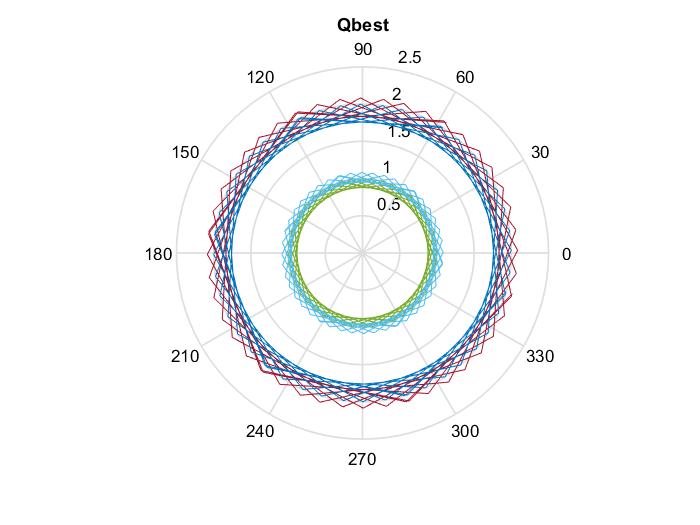

title('Qbest')

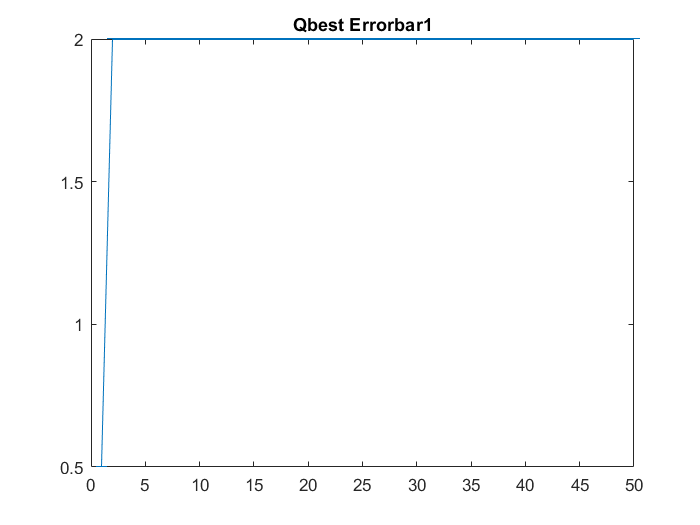

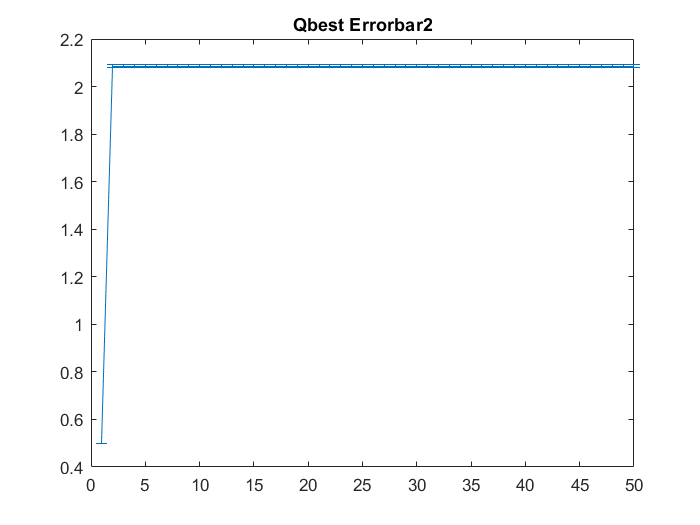

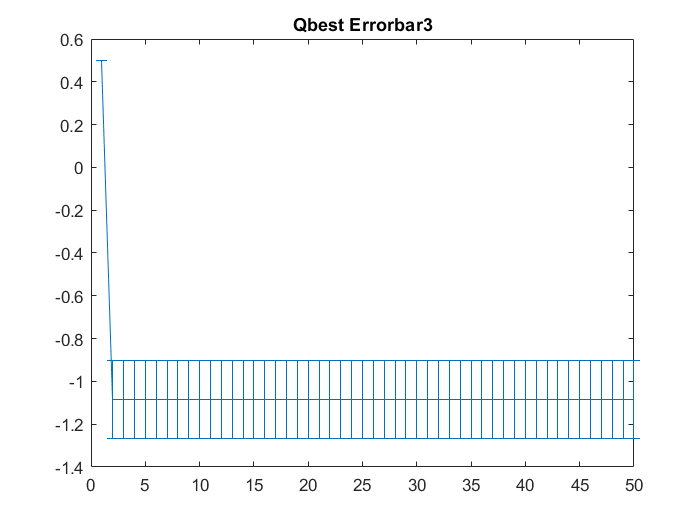

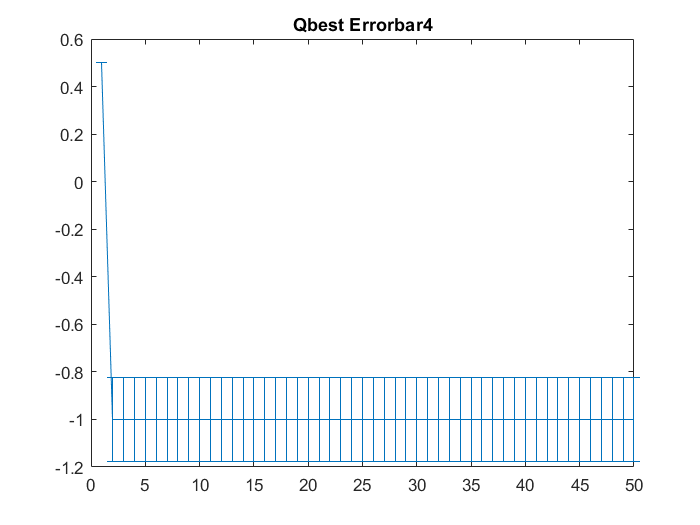

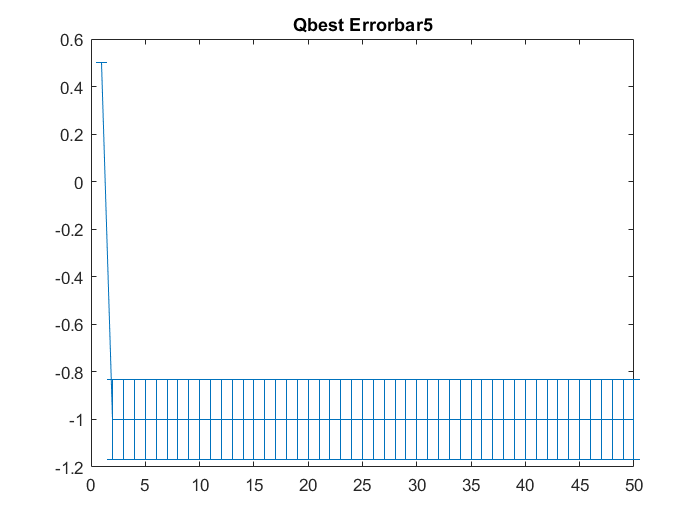

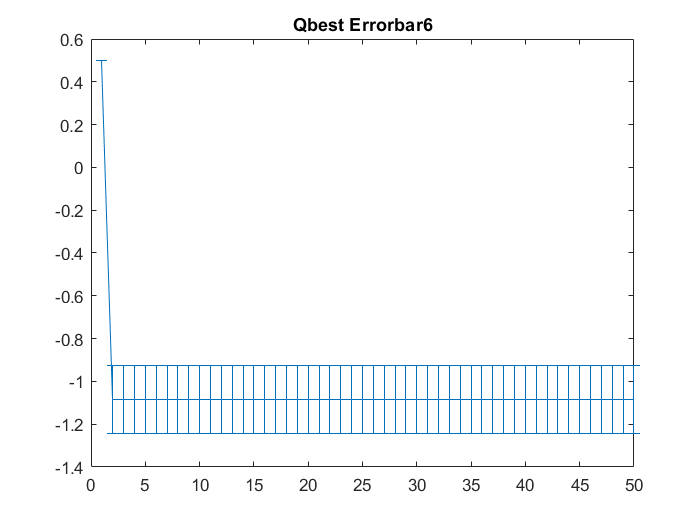

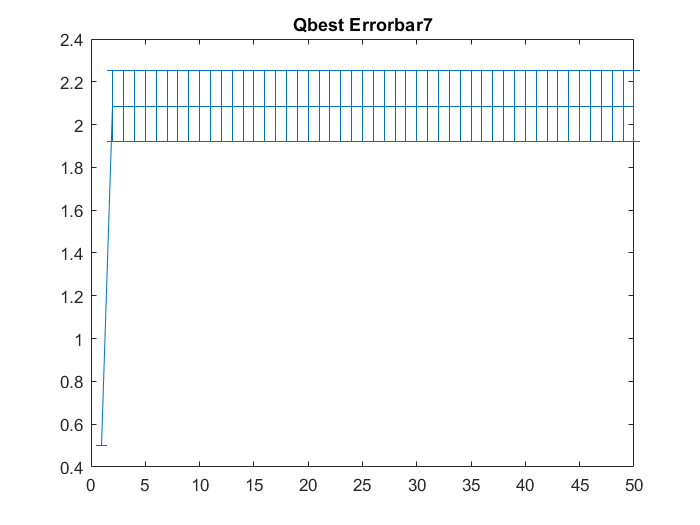

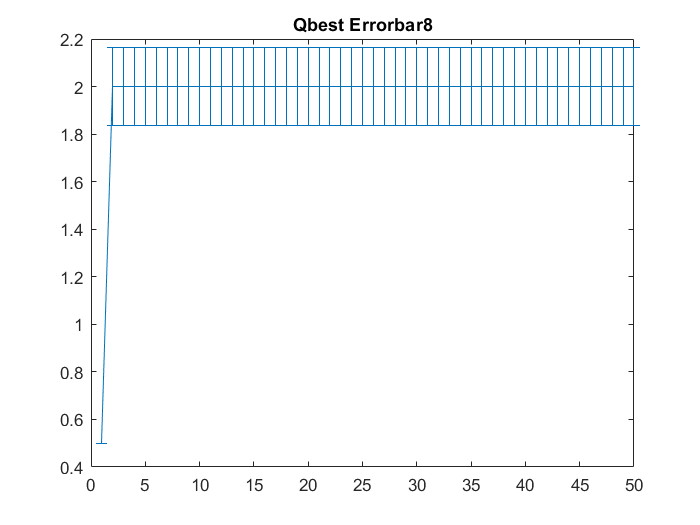

for i = 1:size(meanQbest,1)
    meanQbest(i,:) = mean(temp(1:i,:));
    for j = 1:length(meanQbest(i,:))
        stdQbest(i,j) = std(meanQbest(i,1:j)/10);
    end
end
for i = 1:size(meanQbest,2)
    figure(),
    errorbar(1:size(meanQbest,1), meanQbest(:,i), stdQbest(:,i))
    title(['Qbest Errorbar',num2str(i)])
end


[h,p,ci,stats] = ttest2(Qbest,Qbest);
